addpath(genpath('..'));

dps = load('3dFab_1_deleted_points-SALSA.mat');
dps =  dps.data_points;

[fileName, folderName]=uigetfile('\*.txt','Pick a SALS Output File to Analyze');

dps_p = parseSection(strcat(folderName,fileName));

tissue = data_point.empty;

count = 1;
for i=1:length(dps)
    dp = copy(dps(i));
    if dp.tissue_flag == 1
        count = count + 1;
        tissue = [tissue dp];
    end
end

fs_order = 6;
h = waitbar(0,'Generating tensors');
for data_point_num = 1:length(tissue)
    waitbar(data_point_num/length(tissue));
    data_point_obj1 = tissue(data_point_num);    
    data_point_obj1 = data_point_obj1.Normalize; 
    data_point_obj1 = data_point_obj1.GenerateFourier(fs_order);
    data_point_obj1 = data_point_obj1.ComputeStats;
    tissue(data_point_num) = data_point_obj1;
end
close(h);

fs_order = 6;
h = waitbar(0,'Generating tensors');
for data_point_num = 1:length(dps_p)
    waitbar(data_point_num/length(dps_p));
    data_point_obj1 = dps_p(data_point_num);    
    data_point_obj1 = data_point_obj1.Normalize; 
    data_point_obj1 = data_point_obj1.GenerateFourier(fs_order);
    data_point_obj1 = data_point_obj1.ComputeStats;
    dps_p(data_point_num) = data_point_obj1;
end
close(h);

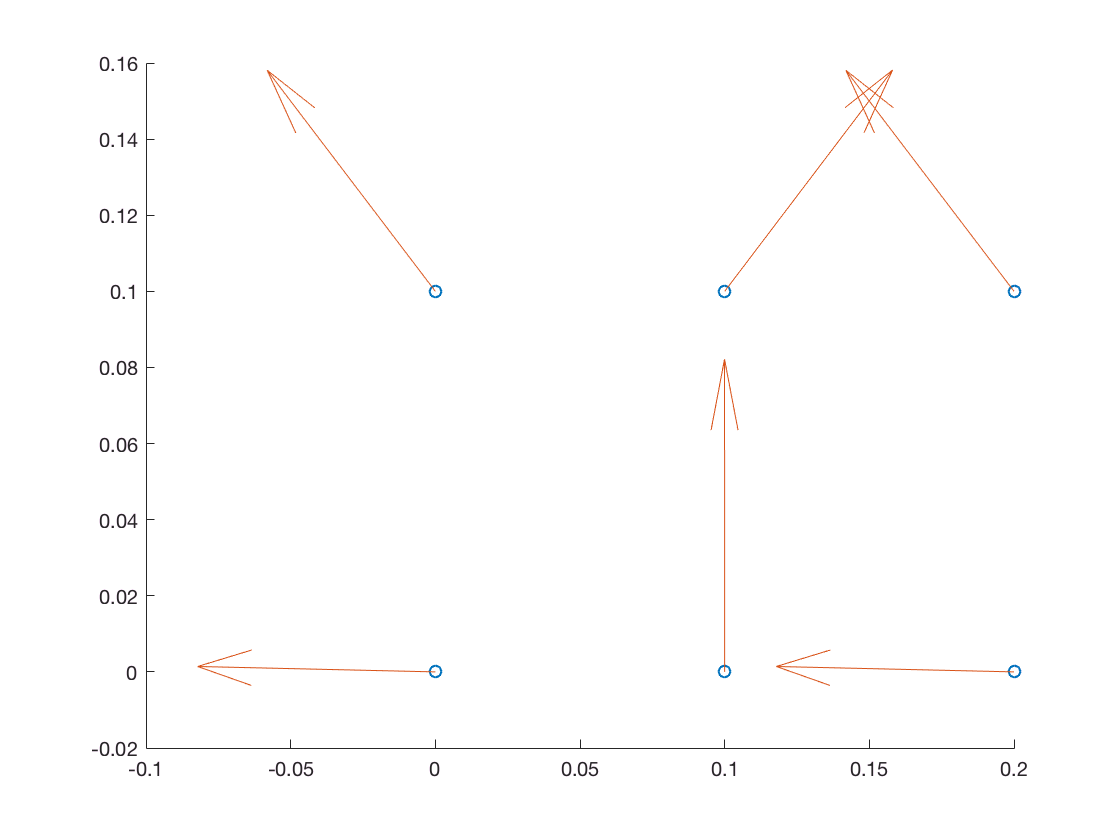

figure
hold on
scatter([tissue(:).x],[tissue(:).y])
u1=cos([tissue(:).mean_odf]);
v1=sin([tissue(:).mean_odf]);
quiver([tissue(:).x],[tissue(:).y], u1,v1)
hold off

figure
hold on
scatter([dps_p(:).x],[dps_p(:).y])
u1=cos([dps_p(:).mean_odf]);
v1=sin([dps_p(:).mean_odf]);
quiver([dps_p(:).x],[dps_p(:).y], u1,v1)
hold off